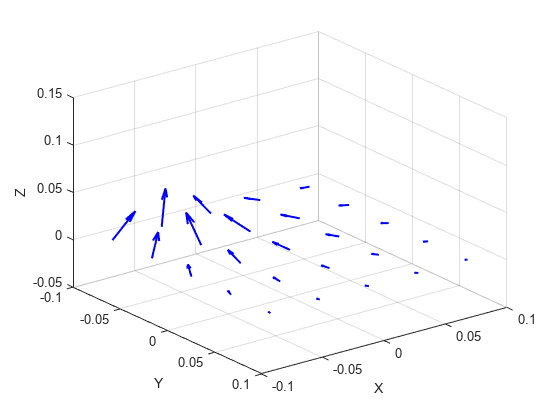

sensor_n = 5; % 传感器行列数
sensor_N = sensor_n^2; % 传感器数量N
sensor_pos = zeros(sensor_N,3); % 传感器位置

sensor_interval_x = 40.14 / 1000; % 传感器间隔x轴，单位转换为米
sensor_interval_y = 41.94 / 1000; % 传感器间隔y轴，单位转换为米

for i = 1:sensor_n % y
    for j = 1:sensor_n % x
        sensor_pos((i-1)*sensor_n + j,1) = ((j-1)-(sensor_n-1)/2)*sensor_interval_x;   % x
        sensor_pos((i-1)*sensor_n + j,2) = ((i-1)-(sensor_n-1)/2)*sensor_interval_y;   % y
        sensor_pos((i-1)*sensor_n + j,3) = 0;                                      % z
    end
end

%%%%%%%%%%%%%%
ser = serialport('COM9',115200); % 打开串口
Bl = 0;
%%%%%%%%%%%%%% 
cnt = 0;
max_loop_times = 10000; % 最大循环次数
while cnt < max_loop_times
    cnt = cnt + 1;
    Bl = serial_parse(ser, sensor_N); % 读取磁场值
    
    Bl(:,1) = - Bl(:,1) + Bl_compensate(:,1); % 地磁场补偿
    Bl(:,2) = Bl(:,2) - Bl_compensate(:,2);
    Bl(:,3) = Bl(:,3) - Bl_compensate(:,3); % Z轴与X、Y相反
    
    quiver3(sensor_pos(:,1),sensor_pos(:,2),sensor_pos(:,3),Bl(:,1),Bl(:,2),Bl(:,3),'-b','LineWidth',1.5);
    % hold on;
    xlim([-0.1 0.1]);
    ylim([-0.1 0.1]);
    zlim([-0.05 0.15]);
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    set(gca,'YDir','reverse');
end

% 永磁体高度
h = 10 / 1000;
% 永磁体真实位置
a = -40 / 1000;
b = -80 / 1000;
c = 95 /1000 + h/2;

% 永磁体真实朝向
m = 0;
n = 0;
p = 1;
H_0 = [m;n;p];
H_0 = normalize(H_0,"norm"); % 归一化向量（按L2范数缩放）

init = 5;
lb = 0; % 下界
ub = 10; % 上界
predict = lsqnonlin(@(param) target_function(param,sensor_pos,Bl,a,b,c,H_0(1),H_0(2),H_0(3)),init,lb,ub)


可能存在局部最小值。

lsqnonlin 已停止，因为平方和相对于其初始值的最终变化小于函数容差值。

<停止条件详细信息>


predict = 5.8493

delete(ser); % 关闭串口

function Bl = serial_parse(ser, N)

Bl = zeros(N,3);

stringLine = readline(ser);
if(strncmp(stringLine,"U",1))
    newStr = strip(stringLine,"U");
    U = sscanf(newStr,"%d");


    stringLine = readline(ser);
    if(strncmp(stringLine,"V",1))
        newStr = strip(stringLine,"V");
        V = sscanf(newStr,"%d");
    end

    stringLine = readline(ser);
    if(strncmp(stringLine,"W",1))
        newStr = strip(stringLine,"W");
        W = sscanf(newStr,"%d");
    end
    
    if(length(U)==N && length(V)==N && length(W)==N)
        Bl(:,1) = U;
        Bl(:,2) = V;
        Bl(:,3) = W;
    end
end
end

function [Blx, Bly, Blz] = MagneticFluxDensityComponent(N_T,m,n,p,a,b,c,x,y,z,noise)
rng default % 为了可重复性，设置默认随机数种子

Rl = sqrt((x-a)^2+(y-b)^2+(z-c)^2);
comm = 3*(m*(x-a)+n*(y-b)+p*(z-c));
Blx = N_T*((comm*(x-a))/(Rl^5)-m/(Rl^3)) + noise*randn;
Bly = N_T*((comm*(y-b))/(Rl^5)-n/(Rl^3)) + noise*randn;
Blz = N_T*((comm*(z-c))/(Rl^5)-p/(Rl^3)) + noise*randn;
end

function F = target_function(param,sensor_pos,Bl,a,b,c,m,n,p)
N_T = param(1);

N = size(sensor_pos,1);
Bpre = zeros(N,3);
for i = 1:N
    [Bpre(i,1),Bpre(i,2),Bpre(i,3)] = MagneticFluxDensityComponent(N_T,m,n,p,a,b,c,sensor_pos(i,1),sensor_pos(i,2),sensor_pos(i,3),0);
    F((i-1)*3 + 1) = Bpre(i,1) - Bl(i,1);
    F((i-1)*3 + 2) = Bpre(i,2) - Bl(i,2);
    F((i-1)*3 + 3) = Bpre(i,3) - Bl(i,3);
end
end